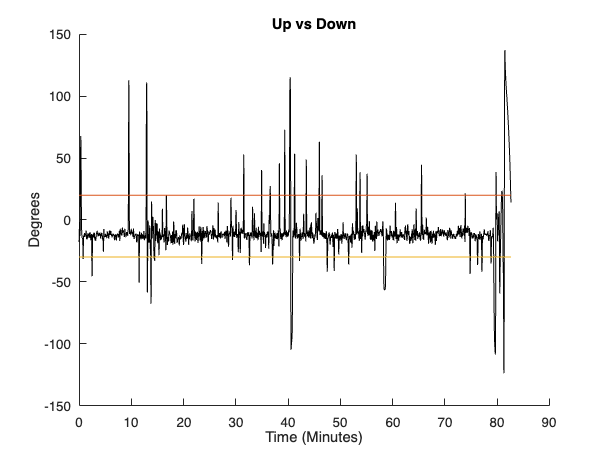

% Set Left and Right Threshold
LR_Threshold = [-30,20];
%Set Up and Down Threshold
UD_Threshold = [20,80];
%Set desired window size, in seconds
window = 120;
fps = 30;


%Call the function head_data to get head angles
[pitch,roll,d] = head_data(coord3D,kioskEnv,optimal_time_head);
%Data Smoothing
pitch = smoothdata(pitch,'gaussian',10*30);
roll = smoothdata(roll,'gaussian',10*30);
%Plot Data of head angles
create_plot(roll,'Up vs Down','Degrees',LR_Threshold)

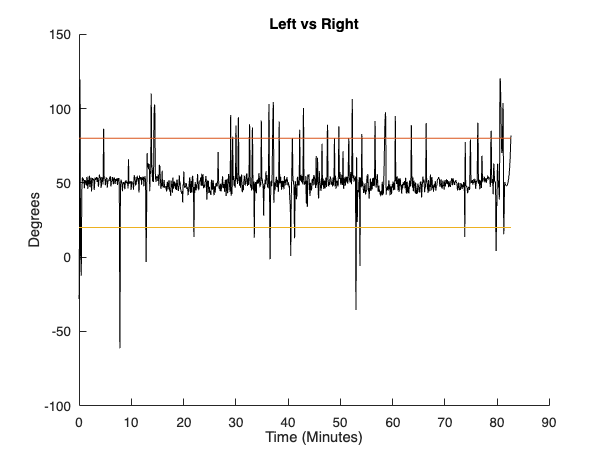

create_plot(pitch,'Left vs Right','Degrees',UD_Threshold)

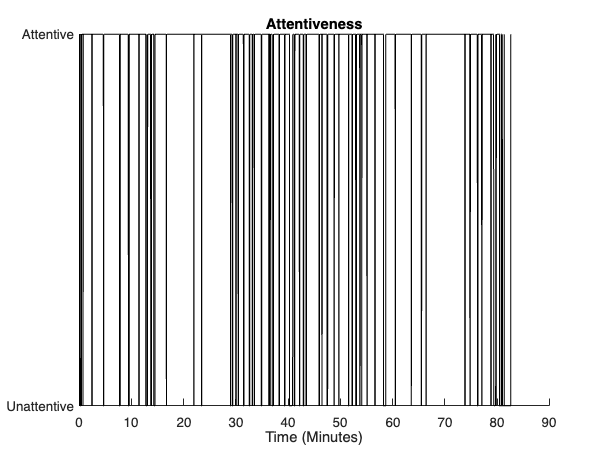


%Classify Attentiveness
attentiveness = attentive(pitch,roll,LR_Threshold,UD_Threshold);

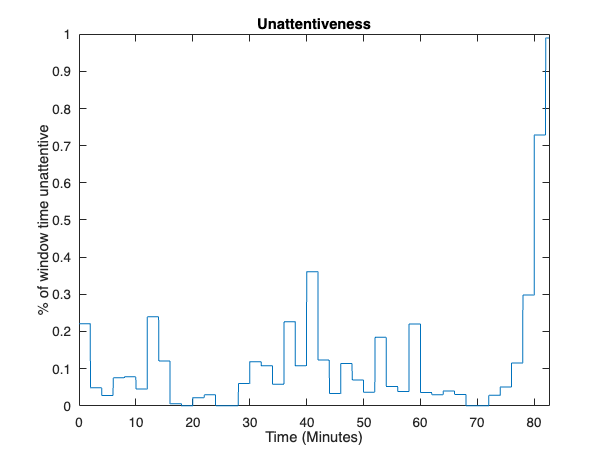

%Summarize Attentiveness Data based on Windows
headFreq = headFrequency(attentiveness,window*fps);






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function freq = headFrequency(data,window)
    % Calculate the number of windows
    num_windows = ceil(length(data) / window);
    
    % Initialize the frequency vector
    freq = zeros(length(data), 1);
    
    % Iterate over each window
    for i = 1:num_windows
        % Define the start and end of the current window
        start_idx = (i - 1) * window + 1;
        end_idx = min(i * window, length(data));
        
        % Calculate the frequency of true values in the current window
        freq_value = window - sum(data(start_idx:end_idx));
        freq_value = freq_value./window;
        
        % Assign the frequency value to the corresponding indices in the freq vector
        freq(start_idx:end_idx) = freq_value;
    end
    time = 1:length(data);
    time = time./30./60;
    plot(time,freq)
    title('Unattentiveness');
    xlabel('Time (Minutes)');
    ylabel('% of window time unattentive');
    axis([0 max(time) 0 1])

end


function attentiveness = attentive(pitch,roll, LR_Threshold,UD_Threshold)
    isAttentive = zeros(1,length(pitch));
    % 
    % mean_data_p = mean(pitch);  % Calculate the mean of the data
    % std_data_p = std(pitch);    % Calculate the standard deviation of the data
    % 
    % % Lines one standard deviation away from the mean
    % upper_p = mean_data_p + 1*std_data_p;  % Mean + 1*Standard Deviation
    % lower_p = mean_data_p - 1*std_data_p;  % Mean - 1*Standard Deviation
    % 
    % mean_data_r = mean(roll);  % Calculate the mean of the data
    % std_data_r = std(roll);    % Calculate the standard deviation of the data
    % 
    % % Lines one standard deviation away from the mean
    % upper_r = mean_data_r + 1*std_data_r;  % Mean + 1*Standard Deviation
    % lower_r = mean_data_r - 1*std_data_r;  % Mean - 1*Standard Deviation
    upper_p = UD_Threshold(end);
    lower_p = UD_Threshold(1);
    upper_r = LR_Threshold(end);
    lower_r = LR_Threshold(1);

    isAttentive(pitch < upper_p & pitch > lower_p & roll < upper_r & roll > lower_r) = 1;

    time = 1:length(pitch);
    time = time./30./60;
    plot(time,isAttentive,'k')
    set(gca,'box','off')
    title('Attentiveness')
    xlabel('Time (Minutes)');
    yticks([0 1]);
    yticklabels({'Unattentive', 'Attentive'});

    
    attentiveness = isAttentive;

end
function create_plot(data,header,y_label,threshold)
    figure
    time = 1:length(data);
    time = time./30./60;
    plot(time,data,'k')
    set(gca,'box','off')
    title(header);
    xlabel('Time (Minutes)');
    ylabel(y_label);
    hold on

    % % Assuming 'data' is your input data array
    % mean_data = mean(data);  % Calculate the mean of the data
    % std_data = std(data);    % Calculate the standard deviation of the data
    % 
    % % Lines one standard deviation away from the mean
    % upper = mean_data + .5*std_data;  % Mean + 1*Standard Deviation
    % lower = mean_data - .5*std_data;  % Mean - 1*Standard Deviation
    

    upper = threshold(end);
    lower = threshold(1);

    upper = ones(size(time)) * upper;
    lower = ones(size(time)) * lower;
    % 
    plot(time, upper)
    plot(time, lower)
    hold off

end
function [pitch,roll,d] = head_data(data,kioskEnv,optimal_time)
    interpupillary_distance = standard(data,optimal_time);

    pitch = zeros(length(data),1);
    yaw = zeros(length(data),1);
    roll = zeros(length(data),1);
    d = zeros(length(data),1);

    screen_plane = find_plane_from_rectangle(kioskEnv);

    for i = 1:length(data)
        face_plane = find_plane(data,i);
        [p, y, r] = align_planes(face_plane, screen_plane);

        pitch(i) = p;
        yaw(i) = y;
        roll(i) = r;

        nose = data(i, 1:3);
        left_eye = data(i, 4:6);
        right_eye = data(i, 7:9);
    
        centroid = (left_eye + right_eye + nose) / 3;
        
        head_center = find_head_center(centroid, face_plane,interpupillary_distance);
        distance = distance_point_to_plane(screen_plane, kioskEnv(1,:), head_center);

        d(i) = distance;
    end
    %     % Plot pitch
    % subplot(2, 2, 1); % Create the first subplot
    % plot(pitch);
    % title('Pitch');
    % xlabel('Time (Frames)');
    % ylabel('Pitch (degrees)');
    % 
    % % Plot yaw
    % subplot(2, 2, 2); % Create the second subplot
    % plot(yaw);
    % title('Yaw');
    % xlabel('Time (Frames)');
    % ylabel('Yaw (degrees)');
    % 
    % subplot(2, 2, 3); % Create the second subplot
    % plot(roll);
    % title('Roll');
    % xlabel('Time (Frames)');
    % ylabel('Roll (degrees)');
    % 
    % % Plot distance
    % subplot(2, 2, 4); % Create the third subplot
    % plot(d);
    % title('Head Distance to Screen');
    % xlabel('Time (Frames)');
    % ylabel('Distance to Screen (mm)');

end
function point = find_head_center(centroid, plane_normal, d)
    % Normalize the plane normal vector
    plane_normal = plane_normal / norm(plane_normal);

    % Calculate the point that is at a distance d from the centroid along the plane normal
    point = centroid - d * plane_normal;
end

function interpupillary_distance = standard(data,time)
    left_eye = data(time,4:6);
    right_eye = data(time,7:9);

    interpupillary_distance = norm(left_eye - right_eye);
end

function [plane_normal, point_on_plane] = find_plane_from_rectangle(rect_vertices)
    % Extract the vertices of the rectangle
    v1 = rect_vertices(1, :);
    v2 = rect_vertices(2, :);
    v3 = rect_vertices(3, :);
    
    % Calculate two vectors on the plane of the rectangle
    vector1 = v2 - v1;
    vector2 = v3 - v2;
    
    % Calculate the normal vector by taking the cross product of the two vectors
    plane_normal = cross(vector1, vector2);
    
    % Normalize the normal vector
    plane_normal = plane_normal / norm(plane_normal);
    
    % A point on the plane can be any of the vertices
    point_on_plane = v1;
end
function distance = distance_point_to_plane(plane_normal, point_on_plane, point)
    % Ensure the normal vector is a unit vector
    plane_normal = plane_normal / norm(plane_normal);
    
    % Compute the vector from the point on the plane to the given point
    vector_to_point = point - point_on_plane;
    
    % Project this vector onto the plane normal vector to find the distance to the plane
    distance = abs(dot(vector_to_point, plane_normal));
end
function [plane_normal, plane_point] = find_plane(data, time)
    % Extract the coordinates of the points
    nose = data(time, 1:3);
    left_eye = data(time, 4:6);
    right_eye = data(time, 7:9);
    
    % Calculate the normal vector of the plane defined by the three points
    v1 = left_eye - nose;
    v2 = right_eye - nose;
    plane_normal = cross(v1, v2);
    plane_normal = plane_normal / norm(plane_normal); % Normalize the plane normal vector

    centroid = (nose + left_eye + right_eye) / 3;
    plane_point = centroid;

end
function [pitch, yaw, roll] = align_planes(plane1, plane2)
    % plane1 and plane2 are in the form [a, b, c, d] representing ax + by + cz + d = 0

    % Extract the normal vectors from the planes
    normal1 = plane1(1:3);
    normal2 = plane2(1:3);

    % Normalize the normal vectors
    normal1 = normal1 / norm(normal1);
    normal2 = normal2 / norm(normal2);

    % Calculate the rotation axis and angle to align normal1 with normal2
    rotation_axis = cross(normal1, normal2);
    rotation_angle = acos(dot(normal1, normal2));

    if norm(rotation_axis) < 1e-6
        % The planes are already aligned
        pitch = 0;
        yaw = 0;
        roll = 0;
        return;
    end

    rotation_axis = rotation_axis / norm(rotation_axis);

    % Create the rotation matrix using Rodrigues' rotation formula
    K = [0, -rotation_axis(3), rotation_axis(2);
         rotation_axis(3), 0, -rotation_axis(1);
         -rotation_axis(2), rotation_axis(1), 0];

    R = eye(3) + sin(rotation_angle) * K + (1 - cos(rotation_angle)) * K^2;

    % Extract pitch, yaw, and roll from the rotation matrix
    sy = sqrt(R(1,1) * R(1,1) +  R(2,1) * R(2,1));

    singular = sy < 1e-6; % If

    if ~singular
        pitch = atan2(R(3,2), R(3,3));
        yaw = atan2(-R(3,1), sy);
        roll = atan2(R(2,1), R(1,1));
    else
        pitch = atan2(-R(2,3), R(2,2));
        yaw = atan2(-R(3,1), sy);
        roll = 0;
    end

    % Convert from radians to degrees
    pitch = rad2deg(pitch);
    yaw = rad2deg(yaw);
    roll = rad2deg(roll);
end
